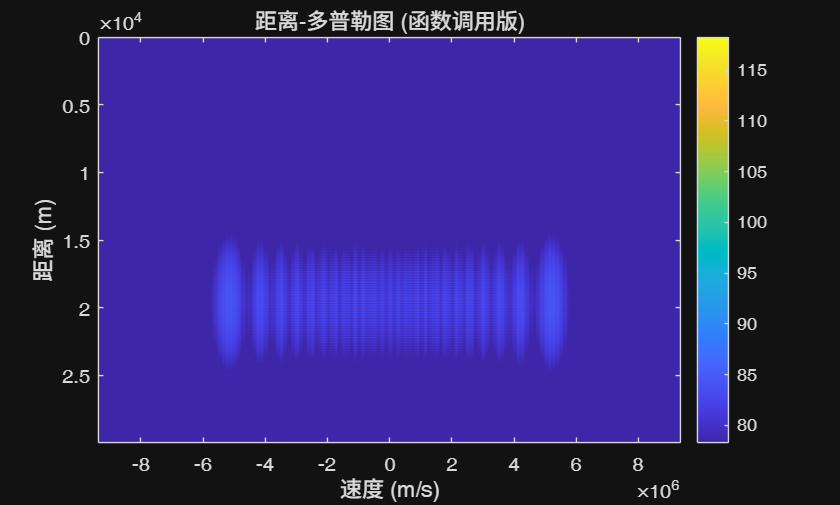

% ==========================================================
% main_process_rdm_functional.m - 调用函数生成距离多普勒图
% ==========================================================
clear; clc; close all;

% 确保 generate_0base_signal.m 和 process_rdm.m 在MATLAB路径中

%% 1. 定义系统和目标参数
% --- 雷达系统参数 ---
params.fs = 80e6;       % 采样频率 80MHz
params.fc = 40e3;       % 中心频率 (用于计算多普勒)
params.B = 10e6;        % 带宽 10MHz
params.taup = 10e-6;    % LFM脉宽 10us
params.Np = 2048;         % 脉冲个数 16
params.PRI = 200e-6;    % 脉冲重复间隔 200us
params.SNR = 20;        % 信噪比 (dB)
params.pos = 10000/2;%10000/2;         % 发射脉冲在PRI内的起始位置

% --- 模拟目标参数 ---
target_R = 10000;       % 目标距离 (m)
target_v = 1000;         % 目标速度 (m/s, 正值表示远离雷达)

% --- 物理常量 ---
c = 3e8;                % 光速 (m/s)

%% 2. 生成发射信号与模拟回波信号
% (调用 `generate_0base_signal` 函数)
[pure_tx, params_out] = generate_0base_signal(params);
jam_params = params_out;
jam_params.JNR = 20; % 距离假目标干扰
jam_params.v = 5e4;           % 拖引速率
[pure_jam] = generate_3rgpo_jamming(pure_tx, jam_params, 1);

% jam_params = params_out;
% jam_params.JNR = 20; % 速度假目标干扰
% jam_params.pull = 5e5;        % 拖引频率 Hz
% [pure_jam] = generate_4vgpo_jamming(pure_tx, jam_params, 1);

tx = pure_tx + pure_jam;

% (模拟回波)
t_delay = 2 * target_R / c;
delay_samples = round(t_delay * params_out.fs);
lambda = c / params_out.fc;
fd = 2 * target_v / lambda;
doppler_phase = exp(1j * 2 * pi * fd * (0:params_out.Np-1) * params_out.PRI);

rx_clean = zeros(size(tx));
for k = 1:params_out.Np
    tx_start = (k-1) * params_out.PRI_samp + params_out.target_start_idx_in_PRI;
    tx_pulse = tx(tx_start : tx_start + params_out.Ntau - 1);
    rx_start = tx_start + delay_samples;
    if (rx_start + params_out.Ntau - 1) <= length(rx_clean)
        rx_clean(rx_start : rx_start + params_out.Ntau - 1) = tx_pulse * doppler_phase(k);
    end
end
signal_power = bandpower(rx_clean);
noise_power = signal_power / (10^(params.SNR/10));
noise = sqrt(noise_power/2) * (randn(size(rx_clean)) + 1j * randn(size(rx_clean)));
rx = rx_clean + noise;

%% 3. 调用函数进行距离多普勒处理
% =====================================================
%  核心调用: 只需一行代码即可完成所有RDM处理!
% =====================================================
[rdm_db, range_axis, velocity_axis] = process_rdm(tx, params_out);
% [rdm_db, range_axis, velocity_axis] = process_rdm_with_keystone(rx, params_out);


%% 4. 可视化距离多普勒图
figure;
imagesc(velocity_axis, range_axis, rdm_db);
colorbar;
xlabel('速度 (m/s)');
ylabel('距离 (m)');
title('距离-多普勒图 (函数调用版)');
clim([max(rdm_db(:))-40, max(rdm_db(:))]); % 调整动态范围

% xlim([-1e6 1e6]);

% 在图上标记真实目标位置
% hold on;
% plot(target_v, target_R, 'r+', 'MarkerSize', 10, 'LineWidth', 2);
% legend('真实目标');
% hold off;
